
Analyzing network width b_n = 200 um with 20 x 20 facets.


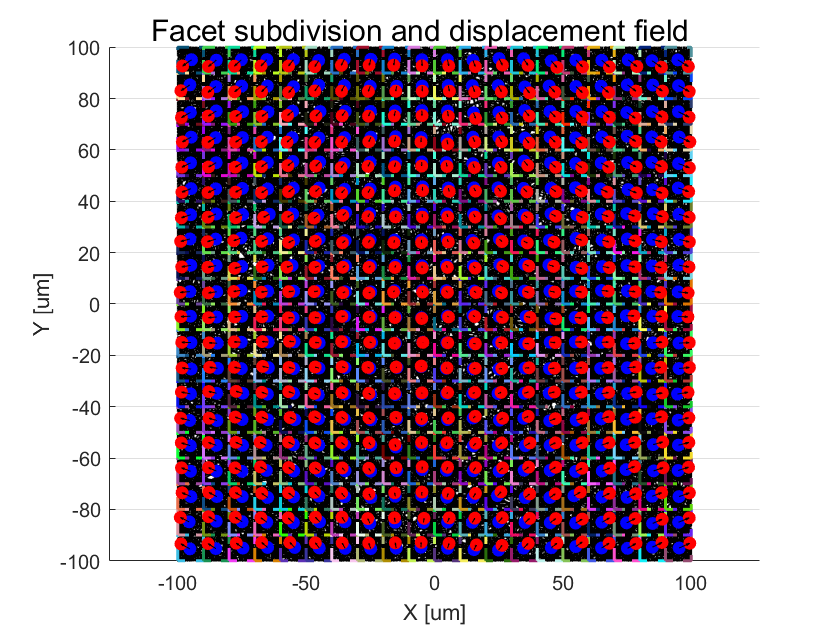

Kinematic fingerprint statistics:


    Quantity        Mean           Std   
    _________    ___________    _________

    "E11"            0.04073    0.0056144
    "E22"          -0.022742    0.0078022
    "E12"        -8.0095e-05    0.0037177
    "R [deg]"    -0.00030501      0.28529
    "m"             -0.59215      0.18295



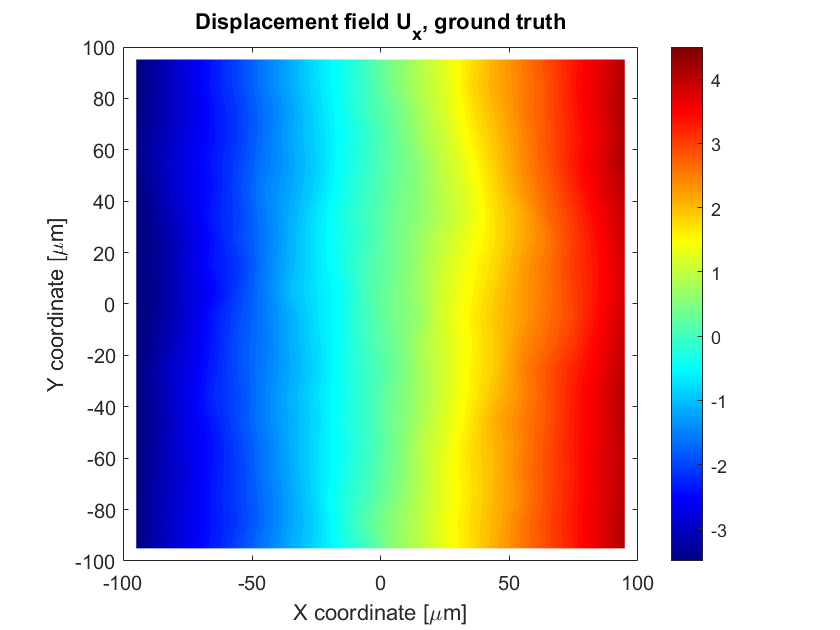

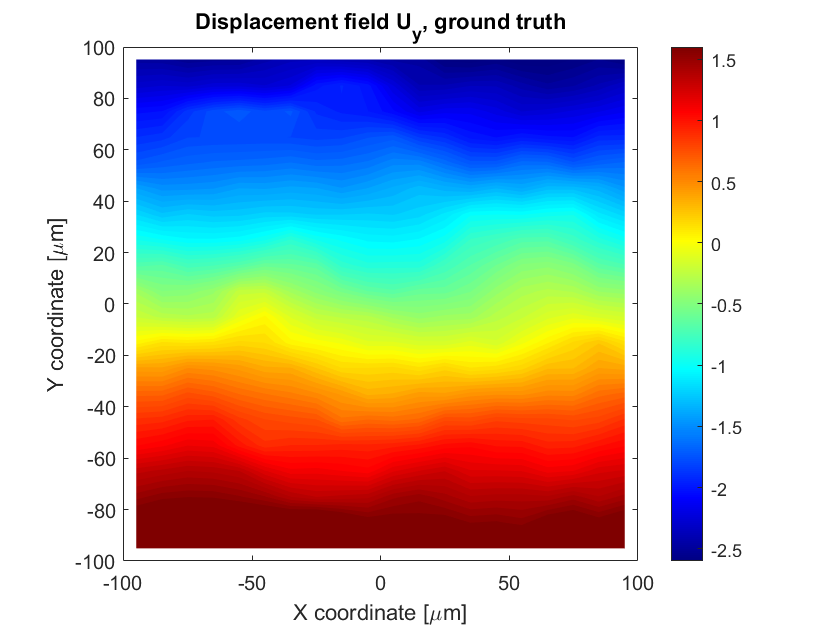

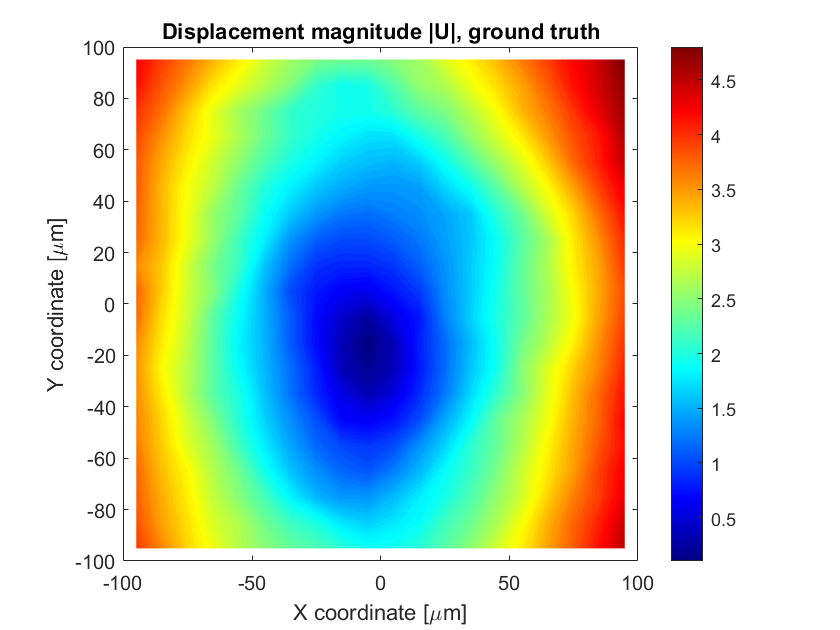

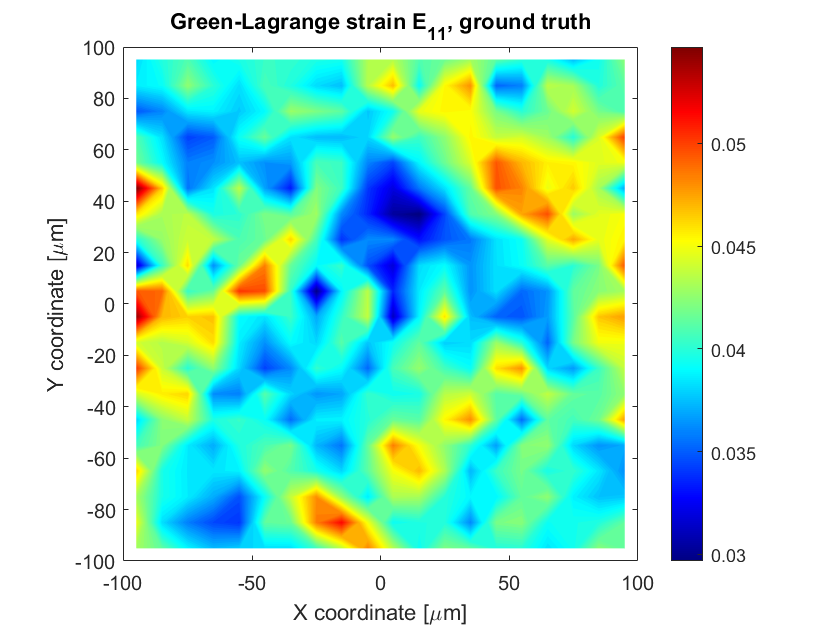

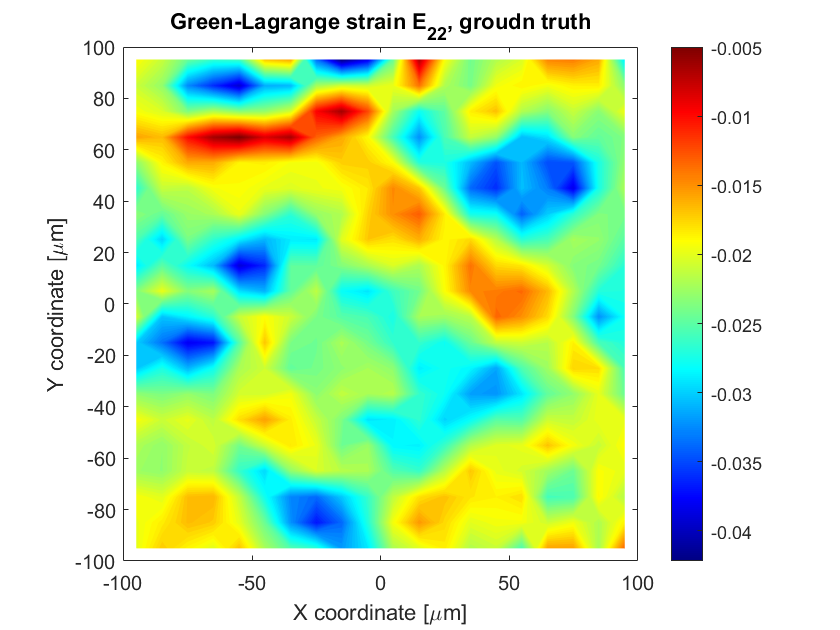

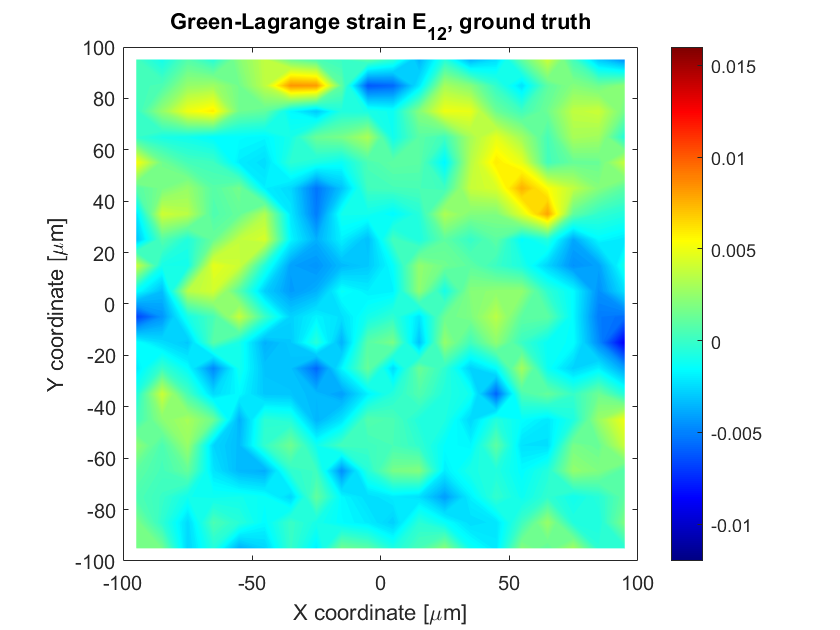

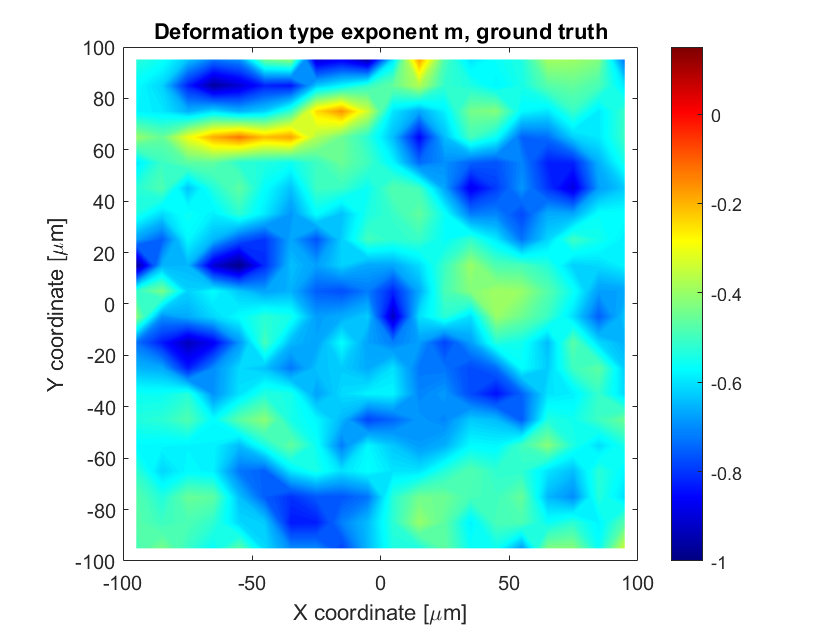

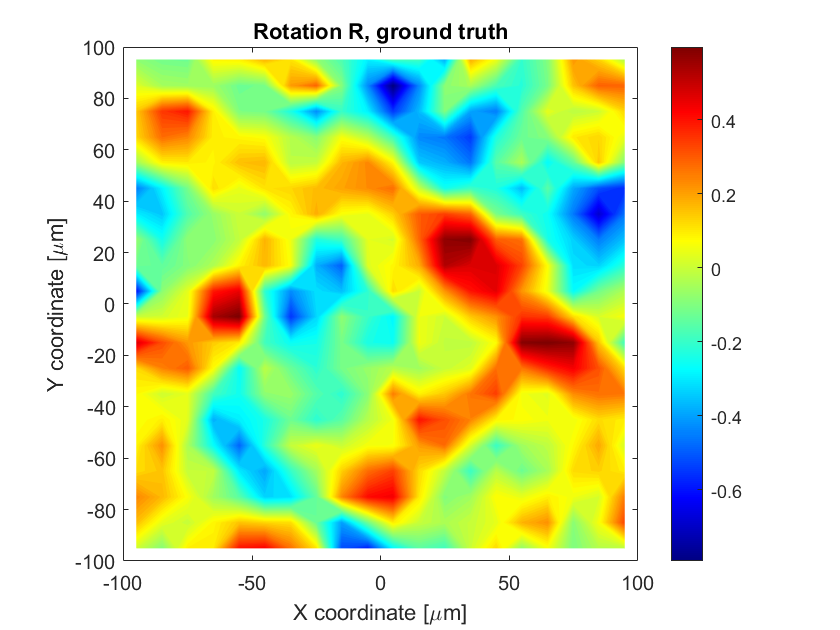

%% Compute local kinematics in electrospun networks from Abaqus nodal coordinates
% This MATLAB script processes nodal coordinates exported from an Abaqus model
% of an electrospun network (ESN). Nodes are assigned to square facets, the
% geometric facet centers are computed in the reference and current
% configurations, and local kinematic quantities are evaluated from the facet
% center displacement field.
%
% Related publication:
%   A continuum mechanics based framework to quantify local kinematics in
%   electrospun networks for mechanobiological investigations
%
% Main quantities:
%   - Deformation gradient F
%   - Green-Lagrange strain components E11, E22, E12
%   - Local rotation angle R
%   - Deformation type exponent m

clc
clear all
tic

% Abaqus coordinate file.
coordinateFile = 'R_200x6xlsm5_plast_viso0_9_UniAx_0_COORD';

% Text file containing the fiber stacking order. The order is used to select a
% depth fraction of the electrospun network.
fiberStackOrderFile = '2024-05-26_R_200x6xlsm5_plast_viso0_9_UniAx_0_fiberstackorder.txt';

% Fraction of fibers to include in the analysis
% Example: upper 20% of fibers:
% fiberFractionUpper = 1.0;
% fiberFractionLower = 0.8;
fiberFractionUpper = 1.0;
fiberFractionLower = 0;

% Facet width(s) b_q to be analyzed
facetWidths = [10];

% Network width(s) b_n to be analyzed
networkWidths = [200];

% Plot settings
plotFacetSubdivision = true;
plotKinematicFields = true;
plotFingerprintHistograms = true;


%% Load input data
load(coordinateFile)   % Loads table COORD

requiredColumns = {'Frame_0_X', 'Frame_0_Y', 'Frame_20_X', 'Frame_20_Y', ...
                   'Part_Instance', 'Node_ID'};

for columnIndex = 1:numel(requiredColumns)
    if ~ismember(requiredColumns{columnIndex}, COORD.Properties.VariableNames)
        error('Required column "%s" is missing in COORD.', requiredColumns{columnIndex})
    end
end

%% Analyze all selected network widths and facet widths
resultsBySetting = cell(numel(networkWidths), 1);

networkWidthIndex = 1;

for networkWidth = networkWidths

    facetWidthIndex = 1;
    numberOfFacetsList = networkWidth ./ facetWidths;

    for numberOfFacets = numberOfFacetsList

        fprintf('\nAnalyzing network width b_n = %.4g um with %d x %d facets.\n', ...
                networkWidth, numberOfFacets, numberOfFacets)

        %% Crop nodal coordinates to the selected network width
        originalWidth = COORD.Frame_0_X(1) * -1 * 2;

        if originalWidth < networkWidth
            error('The selected network width must not be larger than the original model width.')
        end

        halfNetworkWidth = networkWidth / 2;
        nodes = COORD;

        outsideSelectedRegion = nodes.Frame_0_X < -halfNetworkWidth | ...
                                nodes.Frame_0_X >  halfNetworkWidth | ...
                                nodes.Frame_0_Y < -halfNetworkWidth | ...
                                nodes.Frame_0_Y >  halfNetworkWidth;

        nodes(outsideSelectedRegion, :) = [];

        facetWidth = 2 * halfNetworkWidth / numberOfFacets;

        %% Select fibers according to the fiber stacking order
        fiberLines = readlines(fiberStackOrderFile);
        fiberLines = erase(fiberLines, 'F');

        fiberIdString = strjoin(fiberLines);
        fiberIdString = regexprep(fiberIdString, '[^0-9,]', '');
        fiberIdCells = split(fiberIdString, ',');
        fiberStackOrder = str2double(fiberIdCells);
        fiberStackOrder = fiberStackOrder(~isnan(fiberStackOrder));

        numberOfFibers = length(fiberStackOrder);

        firstFiberIndex = floor(numberOfFibers * fiberFractionLower) + 1;
        lastFiberIndex  = floor(numberOfFibers * fiberFractionUpper);

        selectedFiberIds = fiberStackOrder(firstFiberIndex:lastFiberIndex);

        % Keep only nodes that belong to the selected fibers
        nodes = nodes(ismember(nodes.Part_Instance, selectedFiberIds), :);

        %% Create unique node IDs across all fiber instances
        % Abaqus node IDs may repeat between different part instances.
        % Therefore, Part_Instance and Node_ID are combined into one unique ID.

        maxNodeId = max(nodes.Node_ID);
        maxNodeIdDigits = max(1, floor(log10(maxNodeId)) + 1);
        nodeIdMultiplier = 10^maxNodeIdDigits;

        nodes.Node_ID = nodes.Part_Instance * nodeIdMultiplier + nodes.Node_ID;

        %% Define the analysis region and facet grid
        xMin = -halfNetworkWidth;
        xMax =  halfNetworkWidth;
        yMin = -halfNetworkWidth;
        yMax =  halfNetworkWidth;

        stepSizeX = facetWidth;
        stepSizeY = stepSizeX;

        facetNodeIds = cell(numberOfFacets, numberOfFacets);

        %% Assign nodes to square facets
        for xIndex = 0:(numberOfFacets - 1)
            for yIndex = 0:(numberOfFacets - 1)

                currentXMin = xMin + xIndex * stepSizeX;
                currentXMax = currentXMin + facetWidth;

                currentYMin = yMin + yIndex * stepSizeY;
                currentYMax = currentYMin + facetWidth;

                nodesInFacet = nodes(nodes.Frame_0_X >= currentXMin & ...
                                     nodes.Frame_0_X <= currentXMax & ...
                                     nodes.Frame_0_Y >= currentYMin & ...
                                     nodes.Frame_0_Y <= currentYMax, :);

                facetNodeIds{xIndex + 1, yIndex + 1} = nodesInFacet.Node_ID;
            end
        end

        %% Compute geometric facet centers
        % The facet center is the arithmetic mean of all node coordinates inside
        % the corresponding square facet.

        facetCentersRef = nan(numberOfFacets, numberOfFacets, 2);
        facetCentersCur = nan(numberOfFacets, numberOfFacets, 2);

        nodeIds = nodes.Node_ID;

        xRefNodes = nodes.Frame_0_X;
        yRefNodes = nodes.Frame_0_Y;
        xCurNodes = nodes.Frame_20_X;
        yCurNodes = nodes.Frame_20_Y;

        for xIndex = 1:numberOfFacets
            for yIndex = 1:numberOfFacets

                currentNodeIds = facetNodeIds{xIndex, yIndex};

                if ~isempty(currentNodeIds)

                    [isFound, nodeIndices] = ismember(currentNodeIds, nodeIds);
                    nodeIndices = nodeIndices(isFound);

                    if ~isempty(nodeIndices)

                        facetCentersRef(xIndex, yIndex, :) = ...
                            [mean(xRefNodes(nodeIndices)), mean(yRefNodes(nodeIndices))];

                        facetCentersCur(xIndex, yIndex, :) = ...
                            [mean(xCurNodes(nodeIndices)), mean(yCurNodes(nodeIndices))];

                    end
                end
            end
        end

        %% Compute facet-center displacements
        referenceCenterX = facetCentersRef(:, :, 1);
        referenceCenterY = facetCentersRef(:, :, 2);

        currentCenterX = facetCentersCur(:, :, 1);
        currentCenterY = facetCentersCur(:, :, 2);

        displacementX = currentCenterX - referenceCenterX;
        displacementY = currentCenterY - referenceCenterY;

        displacementMagnitude = sqrt(displacementX.^2 + displacementY.^2);

        %% Plot facet subdivision and displacement field
        if plotFacetSubdivision

            figure
            sgtitle('Facet subdivision and displacement field')

            scatter(nodes.Frame_0_X, nodes.Frame_0_Y, 2, 'black', '.')
            hold on

            for xIndex = 0:(numberOfFacets - 1)
                for yIndex = 0:(numberOfFacets - 1)

                    currentXMin = xMin + xIndex * stepSizeX;
                    currentXMax = currentXMin + facetWidth;

                    currentYMin = yMin + yIndex * stepSizeY;
                    currentYMax = currentYMin + facetWidth;

                    plot([currentXMin, currentXMin, currentXMax, currentXMax, currentXMin], ...
                         [currentYMin, currentYMax, currentYMax, currentYMin, currentYMin], ...
                         'LineStyle', '--', ...
                         'Color', rand(1, 3), ...
                         'LineWidth', 1.5)

                    hold on
                end
            end

            plot(referenceCenterX, referenceCenterY, 'bo', 'MarkerFaceColor', 'b')
            plot(currentCenterX, currentCenterY, 'ro', 'MarkerFaceColor', 'r')

            quiver(referenceCenterX, referenceCenterY, displacementX, displacementY, 0, ...
                   'AutoScale', 'off', ...
                   'Color', 'black')

            axis equal
            grid on
            xlabel('X [um]')
            ylabel('Y [um]')

        end

        %% Prepare facet-center matrices for local Q4 evaluation
        facetCenterRefX = rot90(referenceCenterX, 1);
        facetCenterRefY = rot90(referenceCenterY, 1);

        facetCenterCurX = rot90(currentCenterX, 1);
        facetCenterCurY = rot90(currentCenterY, 1);

        [numberOfCenterRows, numberOfCenterColumns] = size(facetCenterRefX);

        numberOfElementRows = numberOfCenterRows - 1;
        numberOfElementColumns = numberOfCenterColumns - 1;

        %% Compute deformation gradients and local kinematic quantities
        % Natural coordinates of the four Q4 element corners.
        %
        % Node order:
        % 1 = lower left
        % 2 = lower right
        % 3 = upper right
        % 4 = upper left

        cornerNaturalCoordinates = [-1 -1;
                                      1 -1;
                                      1  1;
                                     -1  1];

        % Non-averaged local states:
        % element row, element column, corner, component, component

        FLocalAll = nan(numberOfElementRows, numberOfElementColumns, 4, 2, 2);

        E11LocalAll = nan(numberOfElementRows, numberOfElementColumns, 4);
        E22LocalAll = nan(numberOfElementRows, numberOfElementColumns, 4);
        E12LocalAll = nan(numberOfElementRows, numberOfElementColumns, 4);

        rotationRadLocalAll = nan(numberOfElementRows, numberOfElementColumns, 4);
        rotationDegLocalAll = nan(numberOfElementRows, numberOfElementColumns, 4);

        mLocalAll = nan(numberOfElementRows, numberOfElementColumns, 4);

        % Accumulators for visualization fields.
        % Only F is accumulated. E, R, and m are computed later from averaged F.

        sumFAtCenters = zeros(numberOfCenterRows, numberOfCenterColumns, 2, 2);
        numberOfContributions = zeros(numberOfCenterRows, numberOfCenterColumns);

        for elementRow = 1:numberOfElementRows
            for elementColumn = 1:numberOfElementColumns

                % Four facet centers forming one bilinear Q4 element in the
                % reference configuration.

                Xref = [facetCenterRefX(elementRow,     elementColumn),     facetCenterRefY(elementRow,     elementColumn);
                        facetCenterRefX(elementRow,     elementColumn + 1), facetCenterRefY(elementRow,     elementColumn + 1);
                        facetCenterRefX(elementRow + 1, elementColumn + 1), facetCenterRefY(elementRow + 1, elementColumn + 1);
                        facetCenterRefX(elementRow + 1, elementColumn),     facetCenterRefY(elementRow + 1, elementColumn)];

                % Same four facet centers in the current configuration.

                xCur = [facetCenterCurX(elementRow,     elementColumn),     facetCenterCurY(elementRow,     elementColumn);
                        facetCenterCurX(elementRow,     elementColumn + 1), facetCenterCurY(elementRow,     elementColumn + 1);
                        facetCenterCurX(elementRow + 1, elementColumn + 1), facetCenterCurY(elementRow + 1, elementColumn + 1);
                        facetCenterCurX(elementRow + 1, elementColumn),     facetCenterCurY(elementRow + 1, elementColumn)];

                if any(isnan(Xref(:))) || any(isnan(xCur(:)))
                    continue
                end

                % Displacements at the four Q4 nodes
                displacementAtCorners = xCur - Xref;

                for cornerIndex = 1:4

                    xi  = cornerNaturalCoordinates(cornerIndex, 1);
                    eta = cornerNaturalCoordinates(cornerIndex, 2);

                    % Derivatives of the Q4 shape functions with respect to
                    % natural coordinates xi and eta.

                    dN_dNatural = q4_shape_function_derivatives(xi, eta);

                    % Jacobian matrix J = dX/dxi

                    jacobian = Xref.' * dN_dNatural;

                    if abs(det(jacobian)) < 1e-12

                        warning('Singular Jacobian in element (%d,%d), corner %d.', ...
                                elementRow, elementColumn, cornerIndex)

                        continue

                    end

                    % Shape-function derivatives with respect to reference
                    % coordinates X and Y.

                    dN_dReference = dN_dNatural / jacobian;

                    % Deformation gradient using the Q4 displacement field:
                    %
                    % F = I + grad(u)

                    displacementGradient = displacementAtCorners.' * dN_dReference;
                    F = eye(2) + displacementGradient;

                    %% Local non-averaged quantities for kinematic fingerprint
                    C = F.' * F;
                    E = 0.5 * (C - eye(2));

                    E11 = E(1, 1);
                    E22 = E(2, 2);
                    E12 = E(1, 2);

                    rotationTensor = polar_rotation_2D(F);
                    rotationAngleRad = atan2(rotationTensor(2, 1), rotationTensor(1, 1));
                    rotationAngleDeg = rad2deg(rotationAngleRad);

                    mValue = deformation_type_exponent(F);

                    % Store non-averaged local quantities

                    FLocalAll(elementRow, elementColumn, cornerIndex, :, :) = ...
                        reshape(F, 1, 1, 1, 2, 2);

                    E11LocalAll(elementRow, elementColumn, cornerIndex) = E11;
                    E22LocalAll(elementRow, elementColumn, cornerIndex) = E22;
                    E12LocalAll(elementRow, elementColumn, cornerIndex) = E12;

                    rotationRadLocalAll(elementRow, elementColumn, cornerIndex) = rotationAngleRad;
                    rotationDegLocalAll(elementRow, elementColumn, cornerIndex) = rotationAngleDeg;

                    mLocalAll(elementRow, elementColumn, cornerIndex) = mValue;

                    %% Assign this local F contribution to the corresponding facet center
                    switch cornerIndex

                        case 1
                            centerRow = elementRow;
                            centerColumn = elementColumn;

                        case 2
                            centerRow = elementRow;
                            centerColumn = elementColumn + 1;

                        case 3
                            centerRow = elementRow + 1;
                            centerColumn = elementColumn + 1;

                        case 4
                            centerRow = elementRow + 1;
                            centerColumn = elementColumn;

                    end

                    % Accumulate only F for visualization.
                    % E, R, and m for the plotted fields are calculated later
                    % from the averaged F.

                    for rowComponent = 1:2
                        for columnComponent = 1:2

                            sumFAtCenters(centerRow, centerColumn, rowComponent, columnComponent) = ...
                                sumFAtCenters(centerRow, centerColumn, rowComponent, columnComponent) + ...
                                F(rowComponent, columnComponent);

                        end
                    end

                    numberOfContributions(centerRow, centerColumn) = ...
                        numberOfContributions(centerRow, centerColumn) + 1;

                end
            end
        end

        %% Compute averaged fields at facet centers for visualization
        % Important:
        % For the plotted fields, F is averaged first.
        % E11, E22, E12, R, and m are then computed from this averaged F.

        FCenterAverage = nan(numberOfCenterRows, numberOfCenterColumns, 2, 2);

        E11CenterAverage = nan(numberOfCenterRows, numberOfCenterColumns);
        E22CenterAverage = nan(numberOfCenterRows, numberOfCenterColumns);
        E12CenterAverage = nan(numberOfCenterRows, numberOfCenterColumns);

        rotationRadCenterAverage = nan(numberOfCenterRows, numberOfCenterColumns);
        rotationDegCenterAverage = nan(numberOfCenterRows, numberOfCenterColumns);

        mCenterAverage = nan(numberOfCenterRows, numberOfCenterColumns);

        for centerRow = 1:numberOfCenterRows
            for centerColumn = 1:numberOfCenterColumns

                if numberOfContributions(centerRow, centerColumn) > 0

                    %% 1. Average F first
                    Fmean = zeros(2, 2);

                    for rowComponent = 1:2
                        for columnComponent = 1:2

                            Fmean(rowComponent, columnComponent) = ...
                                sumFAtCenters(centerRow, centerColumn, rowComponent, columnComponent) / ...
                                numberOfContributions(centerRow, centerColumn);

                            FCenterAverage(centerRow, centerColumn, rowComponent, columnComponent) = ...
                                Fmean(rowComponent, columnComponent);

                        end
                    end

                    %% 2. Compute Green-Lagrange strain from averaged F
                    Cmean = Fmean.' * Fmean;
                    Emean = 0.5 * (Cmean - eye(2));

                    E11CenterAverage(centerRow, centerColumn) = Emean(1, 1);
                    E22CenterAverage(centerRow, centerColumn) = Emean(2, 2);
                    E12CenterAverage(centerRow, centerColumn) = Emean(1, 2);

                    %% 3. Compute rotation from averaged F
                    rotationTensorMean = polar_rotation_2D(Fmean);
                    rotationAngleRadMean = atan2(rotationTensorMean(2, 1), rotationTensorMean(1, 1));

                    rotationRadCenterAverage(centerRow, centerColumn) = rotationAngleRadMean;
                    rotationDegCenterAverage(centerRow, centerColumn) = rad2deg(rotationAngleRadMean);

                    %% 4. Compute deformation type exponent m from averaged F
                    mCenterAverage(centerRow, centerColumn) = deformation_type_exponent(Fmean);

                end
            end
        end

        %% Kinematic fingerprint vectors
        % These vectors contain the non-averaged local states and are therefore
        % used for the statistical kinematic fingerprint.

        E11Vector = E11LocalAll(:);
        E22Vector = E22LocalAll(:);
        E12Vector = E12LocalAll(:);

        rotationDegVector = rotationDegLocalAll(:);
        rotationRadVector = rotationRadLocalAll(:);

        mVector = mLocalAll(:);

        validLocalState = ~isnan(E11Vector) & ...
                          ~isnan(E22Vector) & ...
                          ~isnan(E12Vector) & ...
                          ~isnan(rotationDegVector) & ...
                          ~isnan(rotationRadVector) & ...
                          ~isnan(mVector);

        E11Vector = E11Vector(validLocalState);
        E22Vector = E22Vector(validLocalState);
        E12Vector = E12Vector(validLocalState);

        rotationDegVector = rotationDegVector(validLocalState);
        rotationRadVector = rotationRadVector(validLocalState);

        mVector = mVector(validLocalState);

        fingerprintTable = table(E11Vector, E22Vector, E12Vector, ...
                                 rotationDegVector, rotationRadVector, mVector, ...
                                 'VariableNames', {'E11', 'E22', 'E12', 'R_deg', 'R_rad', 'm'});

        fingerprintStats = table;

        fingerprintStats.Quantity = ["E11"; "E22"; "E12"; "R [deg]"; "m"];

        fingerprintStats.Mean = [mean(E11Vector); ...
                                 mean(E22Vector); ...
                                 mean(E12Vector); ...
                                 mean(rotationDegVector); ...
                                 mean(mVector)];

        fingerprintStats.Std = [std(E11Vector); ...
                                std(E22Vector); ...
                                std(E12Vector); ...
                                std(rotationDegVector); ...
                                std(mVector)];

        disp('Kinematic fingerprint statistics:')
        disp(fingerprintStats)

        %% Store results for the current analysis setting
        currentResult = struct;

        currentResult.networkWidth = networkWidth;
        currentResult.facetWidth = facetWidth;
        currentResult.numberOfFacets = numberOfFacets;

        currentResult.facetCenters.referenceX = facetCenterRefX;
        currentResult.facetCenters.referenceY = facetCenterRefY;
        currentResult.facetCenters.currentX = facetCenterCurX;
        currentResult.facetCenters.currentY = facetCenterCurY;

        currentResult.displacement.X = rot90(displacementX, 1);
        currentResult.displacement.Y = rot90(displacementY, 1);
        currentResult.displacement.magnitude = rot90(displacementMagnitude, 1);

        % Non-averaged local quantities for the fingerprint
        currentResult.local.F = FLocalAll;
        currentResult.local.E11 = E11LocalAll;
        currentResult.local.E22 = E22LocalAll;
        currentResult.local.E12 = E12LocalAll;
        currentResult.local.R_rad = rotationRadLocalAll;
        currentResult.local.R_deg = rotationDegLocalAll;
        currentResult.local.m = mLocalAll;

        % Averaged plot quantities
        % These are based on Fmean first, then E/R/m are computed from Fmean.
        currentResult.averaged.F = FCenterAverage;
        currentResult.averaged.E11 = E11CenterAverage;
        currentResult.averaged.E22 = E22CenterAverage;
        currentResult.averaged.E12 = E12CenterAverage;
        currentResult.averaged.R_rad = rotationRadCenterAverage;
        currentResult.averaged.R_deg = rotationDegCenterAverage;
        currentResult.averaged.m = mCenterAverage;

        % Fingerprint vectors
        currentResult.fingerprint.E11 = E11Vector;
        currentResult.fingerprint.E22 = E22Vector;
        currentResult.fingerprint.E12 = E12Vector;
        currentResult.fingerprint.R_deg = rotationDegVector;
        currentResult.fingerprint.R_rad = rotationRadVector;
        currentResult.fingerprint.m = mVector;
        currentResult.fingerprint.table = fingerprintTable;
        currentResult.fingerprint.stats = fingerprintStats;

        resultsBySetting{networkWidthIndex}{facetWidthIndex} = currentResult;

        %% Convenience variables for the last analyzed setting
        E11_vec = E11Vector;
        E22_vec = E22Vector;
        E12_vec = E12Vector;

        R_vec = rotationDegVector;
        R_rad_vec = rotationRadVector;

        m_vec = mVector;

        fingerprint_table = fingerprintTable;
        stats = fingerprintStats;

        %% Convenience variables for plotting
        % These variables are useful if your plotting script directly expects
        % matrices with these names.

        E_11 = E11CenterAverage;
        E_22 = E22CenterAverage;
        E_12 = E12CenterAverage;

        phi_all = rotationDegCenterAverage;
        m_all = mCenterAverage;

        F_all_plot = FCenterAverage;

        x_raster = facetCenterRefX;
        y_raster = facetCenterRefY;

%         ArrowLengths_x = rot90(displacementX, 1);
%         ArrowLengths_y = rot90(displacementY, 1);
%         ArrowLengths = rot90(displacementMagnitude, 1);

        half_length = halfNetworkWidth;

        %% Plot averaged kinematic fields
        if plotKinematicFields
            Matlab_009_createPlots_FEM_Matlab_Q4_reference
        end

        %% Plot kinematic fingerprint histograms
        if plotFingerprintHistograms

            figure
            tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact')

            nexttile
            histogram(E11Vector, 'Normalization', 'probability')
            xlabel('E_{11} [-]')
            ylabel('Relative frequency [-]')
            title('E_{11}')

            nexttile
            histogram(E22Vector, 'Normalization', 'probability')
            xlabel('E_{22} [-]')
            ylabel('Relative frequency [-]')
            title('E_{22}')

            nexttile
            histogram(E12Vector, 'Normalization', 'probability')
            xlabel('E_{12} [-]')
            ylabel('Relative frequency [-]')
            title('E_{12}')

            nexttile
            histogram(rotationDegVector, 'Normalization', 'probability')
            xlabel('R [deg]')
            ylabel('Relative frequency [-]')
            title('R')

            nexttile
            histogram(mVector, 'Normalization', 'probability')
            xlabel('m [-]')
            ylabel('Relative frequency [-]')
            title('m')

        end

        facetWidthIndex = facetWidthIndex + 1;

    end

    networkWidthIndex = networkWidthIndex + 1;

end


fprintf('\nComputation completed.\n')


Computation completed.


fprintf('Directly available vectors for the last analyzed setting:\n')

Directly available vectors for the last analyzed setting:


fprintf('E11_vec, E22_vec, E12_vec, R_vec, R_rad_vec, m_vec\n')

E11_vec, E22_vec, E12_vec, R_vec, R_rad_vec, m_vec



toc

Elapsed time is 26.898682 seconds.



%% Local functions
% Local functions must remain at the end of this script.


function dN = q4_shape_function_derivatives(xi, eta)
% Derivatives of bilinear Q4 shape functions with respect to xi and eta.
%
% Node order:
% 1: (-1,-1)
% 2: ( 1,-1)
% 3: ( 1, 1)
% 4: (-1, 1)
%
% The returned matrix has the form:
%
%   [dN1/dxi, dN1/deta;
%    dN2/dxi, dN2/deta;
%    dN3/dxi, dN3/deta;
%    dN4/dxi, dN4/deta]

dN = 0.25 * [-(1 - eta), -(1 - xi);
              (1 - eta), -(1 + xi);
              (1 + eta),  (1 + xi);
             -(1 + eta),  (1 - xi)];

end

function rotationTensor = polar_rotation_2D(F)
% Compute the rotation tensor from the polar decomposition of a 2D
% deformation gradient.
%
% Singular value decomposition:
%
%   F = U*S*V'
%   R = U*V'

[U, ~, V] = svd(F);

rotationTensor = U * V.';

% Avoid numerical reflections
if det(rotationTensor) < 0
    U(:, end) = -U(:, end);
    rotationTensor = U * V.';
end

end

function mValue = deformation_type_exponent(F)
% Compute the deformation type exponent m from the invariants of the right
% Cauchy-Green deformation tensor:
%
%   C = F' * F
%
% The branch structure follows the ESN kinematic fingerprint framework.

C = F.' * F;

Ic1 = trace(C);
Ic2 = det(C);

discriminant = Ic1^2 - 4 * Ic2;

% Correct very small negative values caused by numerical round-off
if discriminant < 0 && abs(discriminant) < 1e-12
    discriminant = 0;
end

if discriminant < 0 || Ic2 <= 0
    mValue = NaN;
    return
end

sqrtDiscriminant = sqrt(discriminant);

lambda1Squared = 0.5 * (Ic1 + sqrtDiscriminant);
lambda2Squared = 0.5 * (Ic1 - sqrtDiscriminant);

if lambda1Squared <= 0 || lambda2Squared <= 0
    mValue = NaN;
    return
end

log1 = log(lambda1Squared);
log2 = log(lambda2Squared);

% Reference state or practically undeformed state
if abs(log1) < 1e-12 && abs(log2) < 1e-12
    mValue = NaN;
    return
end

% Equibiaxial deformation
if abs(log1 - log2) < 1e-12
    mValue = 1;
    return
end

if Ic2 >= 1
    mValue = log2 / log1;
else
    mValue = log1 / log2;
end

end